# AMECH HW11


$$\begin{array}{l}
\vec{F_{\mathrm{cor}} } =-2m\vec{\omega} \times \vec{v} \\
\vec{a_{\mathrm{cor}} } =-2\vec{\omega} \times \vec{v} 
\end{array}$$



$$\begin{array}{l}
\vec{\omega} =\omega \left(\sin \theta \hat{y} +\cos \theta \hat{z} \right)\\
\vec{v} =v_x \hat{x} +v_y \hat{y} ,v_x =0\;\mathrm{for}\;\mathrm{due}\;\mathrm{north},v_y =0\;\mathrm{for}\;\mathrm{due}\;\mathrm{east}
\end{array}$$



$$\vec{a_{\mathrm{cor}} } =-2\vec{\omega} \times \vec{v} =-2\omega \left\lbrack \left(v_z \sin \theta -v_y \cos \theta \right)\hat{x} -\left(-v_x \cos \theta \right)\hat{y} +\left(-v_x \sin \theta \right)\hat{z} \right\rbrack$$



$$\vec{a_{\mathrm{cor}} } =-2\omega \left(\left(v_z \sin \theta -v_y \cos \theta \right)\hat{x} +v_x \cos \theta \hat{y} -v_x \sin \theta \hat{z} \right)$$



$$\begin{array}{l}
F_g =-{\mathrm{mg}}_{\mathrm{eff}} \hat{z} \\
a_g =-g_{\mathrm{eff}} \hat{z} 
\end{array}$$



$$\overset{\ldotp \ldotp }{x} =-2\omega \left(v_z \sin \theta -v_y \cos \theta \right)$$



$$\begin{array}{l}
\overset{\ldotp \ldotp }{y} =-2\omega v_x \cos \theta \\
\overset{\ldotp \ldotp }{z} =-g_{\mathrm{eff}} +2\omega v_x \sin \theta 
\end{array}$$


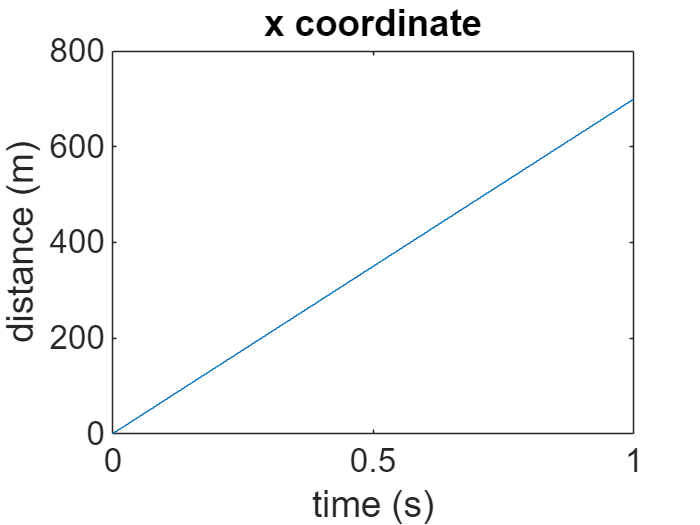

vi = 700 ;
xi = [0, vi, 0, 0, 0, 0] ;
tspan = 0:0.01:1 ;
function xdot = myode(t, x)
    theta = deg2rad(44.9778) ;
    omega = 7.2921*10^(-5) ;
    g = 9.8 -(omega^2*(6378137)*cos(theta)) ;
    z = x(5:6) ;
    y = x(3:4) ;
    x = x(1:2) ;
    xdot(1) = x(2) ;
    xdot(2) = -2*omega*(z(2)*sin(theta) - y(2)*cos(theta)) ;
    ydot(1) = y(2) ;
    ydot(2) = -2*omega*x(2)*cos(theta) ;
    zdot(1) = z(2) ;
    zdot(2) = -g+2*omega*x(2)*sin(theta) ;
    xdot = [xdot(1), xdot(2), ydot(1), ydot(2), zdot(1), zdot(2)]' ;
end
[t, x] = ode45(@myode, tspan, xi) ;
clf
figure
plot(t, x(:, 1))
set(gca, 'fontsize', 20)
ylabel('distance (m)')
xlabel('time (s)')
title('x coordinate')

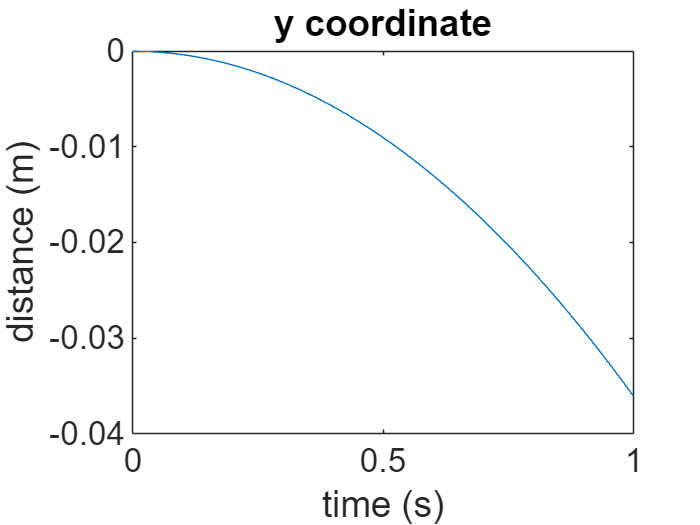

plot(t, x(:, 3))
title('y coordinate')
set(gca, 'fontsize', 20)
ylabel('distance (m)')
xlabel('time (s)')

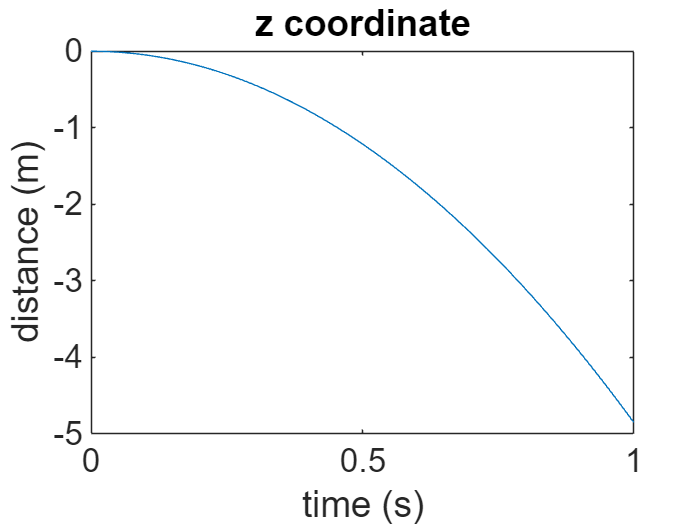

plot(t, x(:, 5))
title('z coordinate')
set(gca, 'fontsize', 20)
ylabel('distance (m)')
xlabel('time (s)')

y_f = x(end, 3) 

y_f = -0.0361

z_f = x(end, 5)

z_f = -4.8519

% Correct with these values
xi = [0, vi, 0.0361, 0, 4.8519, 0] ;
[t, x] = ode45(@myode, tspan, xi) ;
clf
figure
plot(t, x(:, 1))
set(gca, 'fontsize', 20)
ylabel('distance (m)')
xlabel('time (s)')
title('x coordinate')

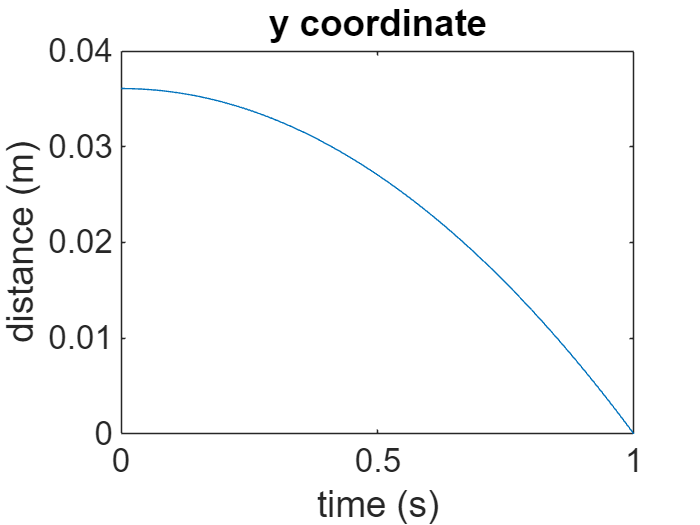

plot(t, x(:, 3))
title('y coordinate')
set(gca, 'fontsize', 20)
ylabel('distance (m)')
xlabel('time (s)')

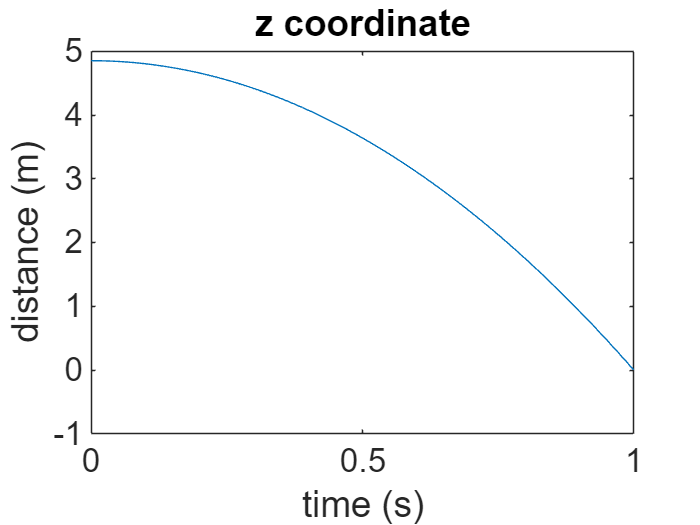

plot(t, x(:, 5))
title('z coordinate')
set(gca, 'fontsize', 20)
ylabel('distance (m)')
xlabel('time (s)')